# Network states during each tasks in the order they were performed

# Things to do

### Things To Do for this analysis

Still need to make into a read me file

### Other Things To Do

subject assignment to conditions, need to know how to describe

order of tasks, random?

Make New plots of new claims in sfn abstact (if indeed are true

Use clustered regression techniques as discussed with jodi

- initial methods, for samples at 2 time points:

-  - Clustered robust standard error regression R package to use: huber white standard  regrsion package

- More complex method, for more that 2 time points:

- - longitudinal mixed models

- - New plots of new SFN claims

using wpli matrix, create a graph structure!!!! 

Assess visually using using matlabs graph structure and  wpli matrix\

recreate figure 2 with new data frame

recreate figure 3 with new data frame and topoplot functionality

# Eperimental Time Course

The experiment has two intevention sessions. Each session has 4 test bouts that last about 15 minutes. Within each test bout there is a 'battery' of tests being conducted.

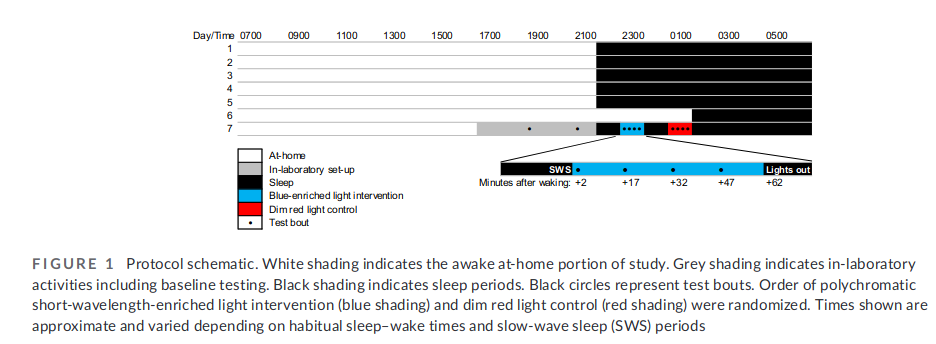

Notice that the PV task is performed first, followed by Math, GoNogo and finall the KD task. 

- 5 min PVT

- 1min KSS/MOOD (subjective scales)

- 2-3min MATH (addition task)

- 2-3min GONOGO (response inhibition task)

- 1min PERF (subjective performance scale)

- 3 min KDT (sitting staring at dot for clean EEG)

This process is repeated 4 times.

Below we show the detailed time course of the network accross the experiment. Namely

youll see the state of the network as subjects engage in each of the four tasks in the order they were performed.

This is shown seperately for the the control condition and the light condition.

# First retreive Master Data Set

DF = dfmaster;


Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done

Getting GPSD during KDT Task. . . . . . . . . . . -done

Getting Network Props during KDT: . . . . . . . . . . . -done

Getting GPSD during MATH Task. . . . . . . . . . . . -done

Getting Network Props during MATH: . . . . . . . . . . . . -done

Getting GPSD during GONOGO Task. . . . . . . . . . . . -done

Getting Network Props during GONOGO: . . . . . . . . . . . . -done


# Show the time course of GLOBAL POWER

#### Time course POWER during the CONTROL session 

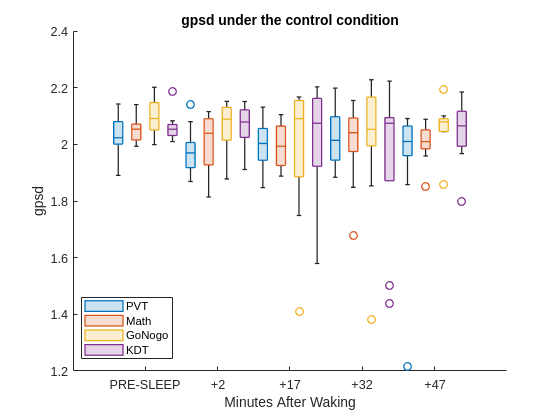

figure
nexttile
df =  extractsubdf(DF, 'gpsd', 'control');
plotboxes(df,'gpsd', 'control');

#### Time course POWER during the LIGHT session 

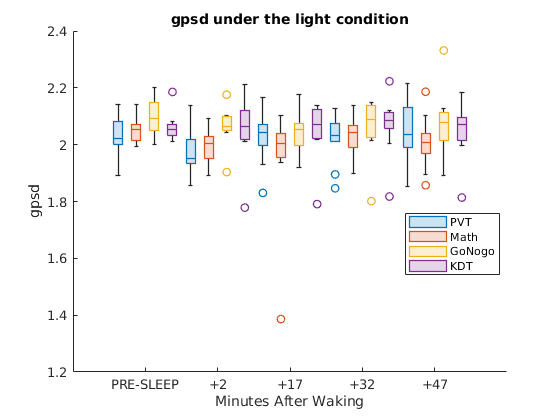

figure
nexttile
df =  extractsubdf(DF, 'gpsd', 'light');
plotboxes(df,'gpsd', 'light');

# Show the time course of the CLUSTERING COEFFICENT

#### Time course of the CLUSTERING coefficient during the CONTROL session 

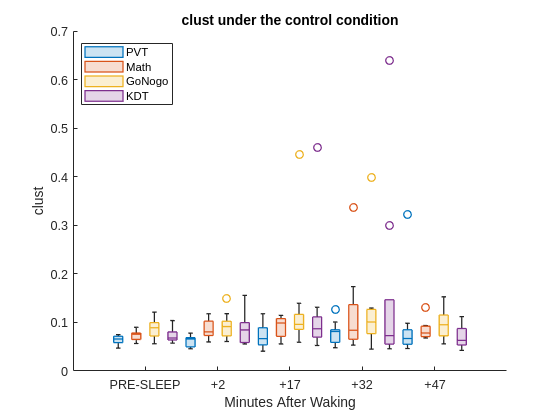

figure
nexttile
df =  extractsubdf(DF, 'clust', 'control');
plotboxes(df,'clust', 'control');

#### Time course of the CLUSTERING during the LIGHT session 

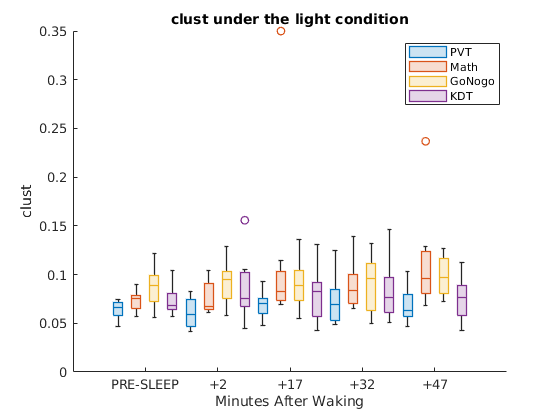

figure
nexttile
df =  extractsubdf(DF, 'clust', 'light');
plotboxes(df,'clust', 'light');

# Show the time course of PATH LENGTH

#### Time course of *PATH LENGTH* during the *CONTROL *session 

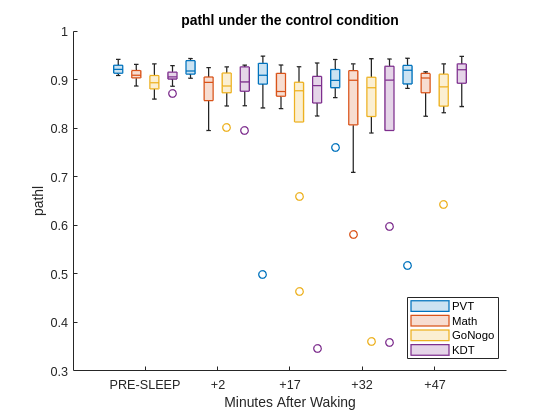

figure
nexttile
df =  extractsubdf(DF, 'pathl', 'control');
plotboxes(df,'pathl', 'control');

#### Time course of *PATH LENGTH* during the LIGHT session 

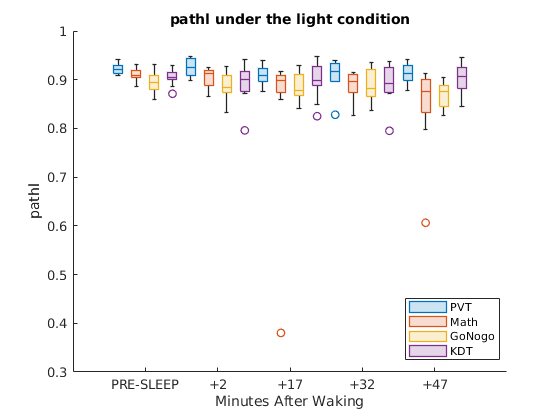

figure
nexttile
df =  extractsubdf(DF, 'pathl', 'light');
plotboxes(df,'pathl', 'light');

## Functions

### Function extract subset of master data set

function dfsubset = extractsubdf(DF, ntwprop, cond)
    getdf           = @(cogtest, ntwprop, cond) DF((DF.cogtest == cogtest) & (DF.ntwprop == ntwprop) & (ismember(DF.sbj,goodsbj(cogtest))) & ( (DF.condition == cond) | (DF.condition == 'baseline') ),:);
    averageacross   = @(df) varfun(@mean, df, "InputVariables","Y","GroupingVariables",{'ntwprop', 'cogtest', 'run', 'condition', 'sbj'});
    getgroupeddf    = @(cogtest, ntwprop, cond) averageacross(getdf(cogtest, ntwprop, cond)); 
    getfinaldf      = @(ntwprop, cond)[getgroupeddf('PVT', ntwprop, cond); getgroupeddf('Math', ntwprop, cond); getgroupeddf('GoNogo', ntwprop, cond); getgroupeddf('KDT', ntwprop, cond)];
    dfsubset        = getfinaldf(ntwprop, cond);
end

### To create boxcharts, need to convert test bout and task type into ordinal variables

function plotboxes(df, networkprop, condition)
    df.cogtest  = categorical(df.cogtest,{'PVT', 'Math', 'GoNogo', 'KDT'}, 'Ordinal',true);
    df.run      = categorical(df.run,[0, 1, 2, 3, 4], 'Ordinal',true);
    df.run      = renamecats(df.run,{'PRE-SLEEP', '+2' '+17', '+32','+47'});
    df          = sortrows(df,{'run', 'cogtest'});

    boxchart(df.run, df.mean_Y, 'GroupByColor',df.cogtest)   ;
    ylabel(networkprop)
    title(sprintf('%s under the %s condition', networkprop,condition ));
    xlabel('Minutes After Waking')
    legend('Location','best')    

end

## ___

____

___